# SPOSOBY POMIARU PODOBIEŃSTWA MIĘDZY UTWORAMI MUZYCZNYMI ORAZ OBRAZAMI.

## Wyczyszczenie danych skryptu, dodanie folderu z narzędziami do zmiennej środowiskowej

clear variables;
addpath(genpath('MATLAB_SM-Toolbox_1.0'));

## Przygotowanie ścieżek do plików dla analizy dźwięku

file = 'Audio/Nirvana - Come As You Are.mp3';
file1 = 'Audio/Come As You Are Unplugged(f).wav';
file2 = 'Audio/Come As You Are(f).wav';

## Przygotowanie pliku do analizy

Aby możliwe było stworzenie macierzy podobieństwa plik musi zostać odpowiednio przygotowany. W pierwszym kroku, który realizuje funkcja wav_to_audio następuje konwersja formatu WAV z dowolną częstotliwością próbkowania na WAV mono z próbkowaniem 22050 Hz.

Następnie funkcja audio_to_pitch zapewnia dekompozycję danego audio na 88 pasm częstotliwości z częstotliwością środkową odpowiadającą wysokościom tonów od A0 do C8.

pitch_to_CENS - CENS(Chroma Energy Normalized Statistics) to grupa skalowalnych cech dźwięku mających związek z krótkoczasową zawartością harmonicznych i zawierają znaczącą ilość iformacji takich jak dynamika, barwa, artykulacja oraz czasowe mikro-odchylenia.

pitch_parameters = struct('winLenSTMSP', 4410);
CENS_parameters = struct('winLenSmooth', 11, 'downsampSmooth', 5);
visualization_parameters = struct('colormapPreset', 2);
threshold_parameters = struct('threshTechnique', 1, 'threshValue', 0.7, 'applyBinarize', 1);

audio = audio_from_file('', '', file);
pitch = audio_to_pitch_via_FB(audio, pitch_parameters);

Computing subbands and STMSP for all pitches: (21-108):  108


cens = pitch_to_CENS(pitch, CENS_parameters);

audio1 = audio_from_file('', '', file1);
pitch1 = audio_to_pitch_via_FB(audio1, pitch_parameters);

Computing subbands and STMSP for all pitches: (21-108):  108


cens1 = pitch_to_CENS(pitch1, CENS_parameters);

audio2 = audio_from_file('', '', file2);
pitch2 = audio_to_pitch_via_FB(audio2, pitch_parameters);

Computing subbands and STMSP for all pitches: (21-108):  108


cens2 = pitch_to_CENS(pitch2, CENS_parameters);

## Zasada działania i powstawania macierzy podobieństwa.

Macierz podobieństwa pozwala na pomiar podobieństwa między dwoma obiektami. Istnieje wiele sposobów pomiaru podobieństwa, w tym przypadku wykorzystana została metoda cosinusów (cosine similarity). Wynikami są liczby rzeczywiste, przy czym im większa wartość tym większe podobieństwo. Pojęcie macierzy podobieństwa ma szerokie zastosowanie w analizie muzycznej, analizie struktury dżwięków oraz ich rozpoznawaniu. Wartość 0 w macierzy oznacza całkowity brak podobieństwa, natomiast wartośc 1 oznacza fragmenty identyczne.

## Generacja macierzy podobieństwa

SM_Self = features_to_SM(cens, cens);
SM_Self_Thresholded = threshSM(SM_Self, threshold_parameters);

SM = features_to_SM(cens1, cens2);
SM_Thresholded = threshSM(SM, threshold_parameters);

## SM thresholded

Macierz podobieństwa przetworzona poprzez blokowanie wartości mniejszych od podanego progu. Taki zabieg pozwala na redukcję szumu i pozyskanie czytelniejszego wykresu. Istnieje jednak możliwość zatracenia w ten sposób istotnych informacji. 

## Wyświetlenie macierzy podobieństwa

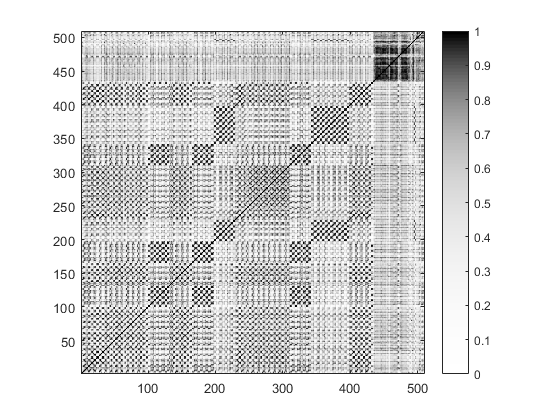

visualizeSM(SM_Self, visualization_parameters);

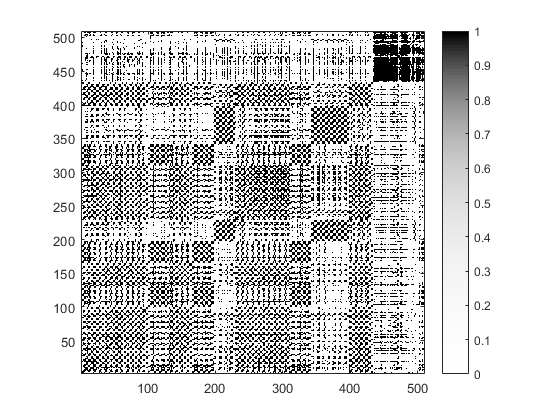

visualizeSM(SM_Self_Thresholded, visualization_parameters);

## Wnioski z analizy samopodobieństwa utworu: 

Analizowany utwór wykazuje duże samopodobieństwo, widoczny jest podział macierzy odwzorowujący frazy i motywy muzyczne w badanym utworze. Macierz samopodobieństwa odzwierciedla strukturę utworu. Mozna zauważyć, że cały utwór jest do siebie podobny, co jest prawdą, z racji motywu, który przewija się poprzez cały czas trwania utworu. Górny róg macierzy odzwierciedla prawie całkowite podobieństwo - wniosek: na końcu nagrania emitowany jest jeden i ten sam ton, lub znajduje się tam cisza, co znajduje potwierdzneie w rzeczywistym nagraniu.

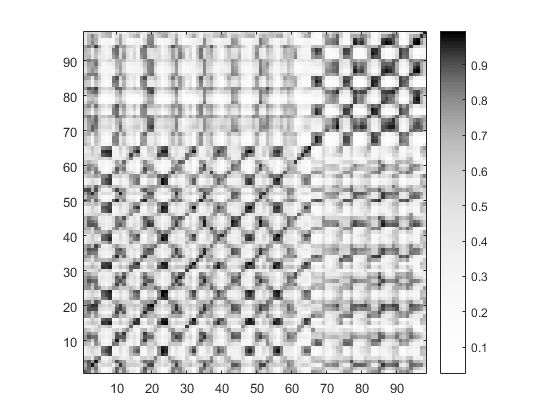

visualizeSM(SM, visualization_parameters);

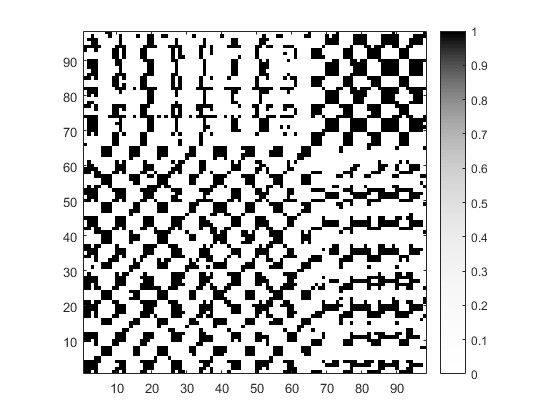

visualizeSM(SM_Thresholded, visualization_parameters);

## Wnioski z analizy podobieństwa utworu z dwóch nagrań live:

Przeanalizowano ten sam fragment utworu z dwóch nagrań live. Na macierzach widać że linia biegnąca przez przekątną jest dośc widoczna co oznacza, że w tym samym momencie danego utworu pojawiają się te same motywy, dowodzi to iż analizowane utwory są tymi samymi, tylko w różnych wykonaniach. Brak całkowitego podobieństwa(wartości 1 w macierzy) pokazuje iż wykonania są różne, pochodzą z dwóch różnych nagrań z różnych miejsc.

# BADANIE PODOBIEŃSTWA OBRAZÓW

## Wczytanie obrazów

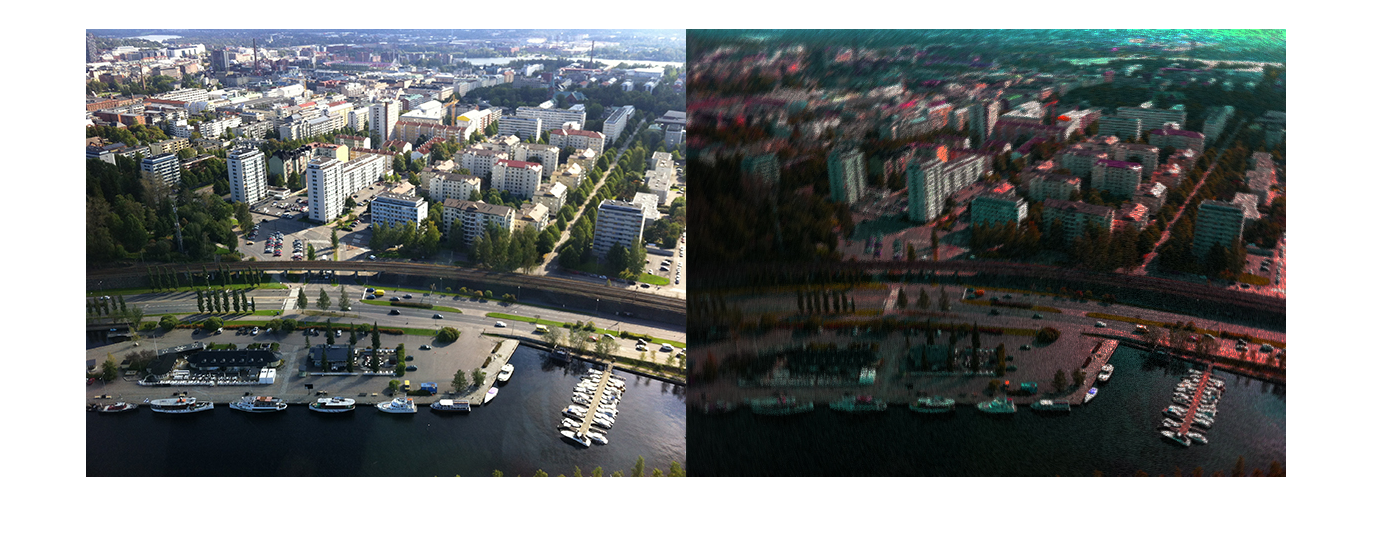

im_path1 = 'Photo/basic.jpg';
im_path2 = 'Photo/filtered.jpg';
image1 = imread(im_path1);
image2 = imread(im_path2);
imshowpair(image1, image2, 'montage');

## 1.

Oblicza i tworzy wizualicazję różnic między dwoma obrazami, obszary w skali szarości to te ktore sa takie same.

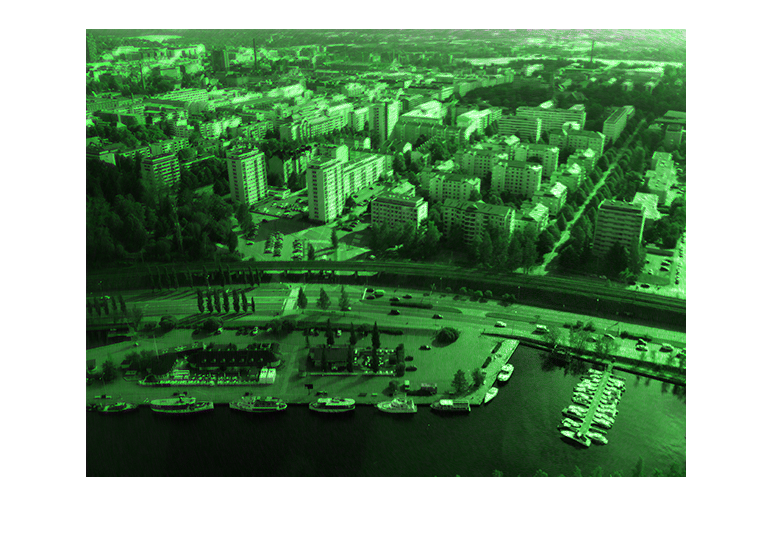

figure(10);
obj = imshowpair(image1, image2);

Obraz jest zielony, co oznacza że kolory w żadnym miejscu obrazu nie są takie same.

## 2.

The Structural Similarity (SSIM) - służy do porównania jakości obrazu względem obrazu referencyjnego na podstawie kontrastu, struktury oraz naświetlenia. Końcowe wyniki są kombinacją tych trzech elementów. 

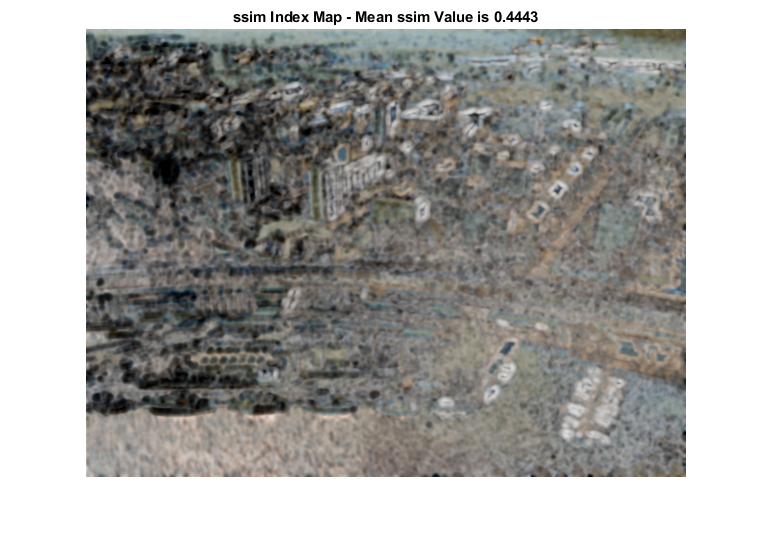

[SSIMVAL, SSIMMAP] = ssim(image1, image2);
figure(11);
imshow(SSIMMAP,[]);
title(sprintf("ssim Index Map - Mean ssim Value is %0.4f",SSIMVAL));

## 3.

Maksymalmy stosunek sygnału do szumu.

PEAKSNR = psnr(image1, image2)

PEAKSNR = 12.0367

## KONWERSJA RGB NA SKALĘ SZAROŚCI

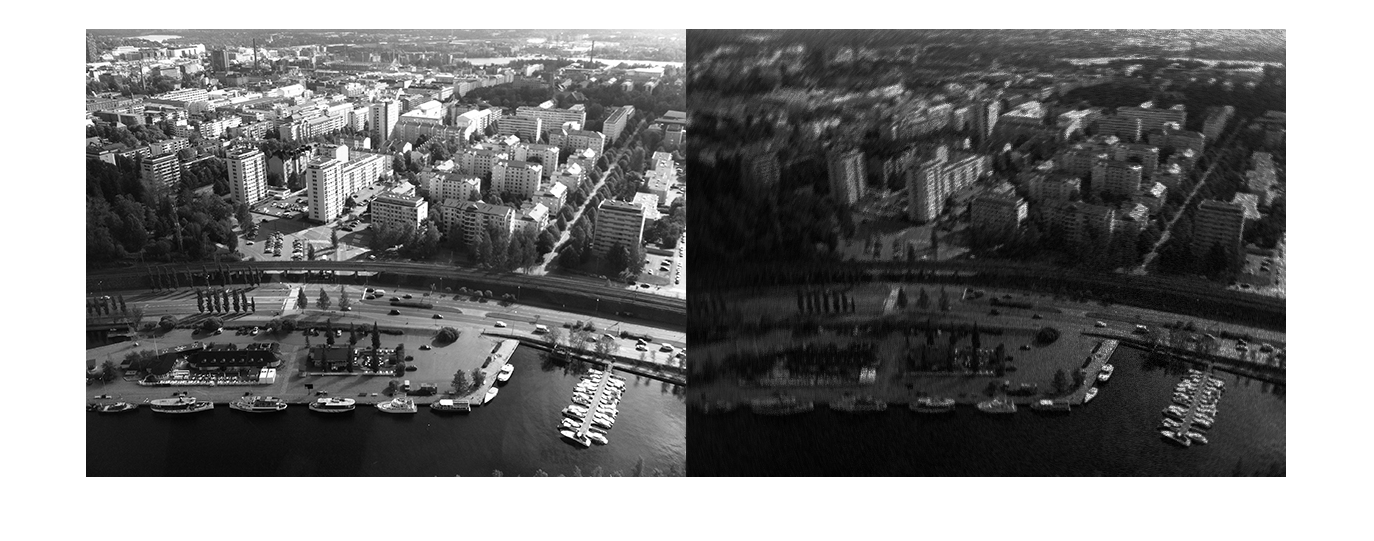

image1_gray = rgb2gray(image1);
image2_gray = rgb2gray(image2);
imshowpair(image1_gray, image2_gray, 'montage');

## 4.

Współczynnik korelacji określający w jakim stopniu zmienne są współzależne.

R = corr2(image1_gray, image2_gray)

R = 0.9008

Dośc wysoki współcznnik korelacji oznacza, że obrazy są do siebie dośc mocno podobne, gdyby nałożyc na drugi obraz więcej efektów, lub zmienić jego kształt współczynnik korelacji byłby dużo niższy.

## 5.

Histogram porównujący zawartość pikseli o danym odcieniu szarości.

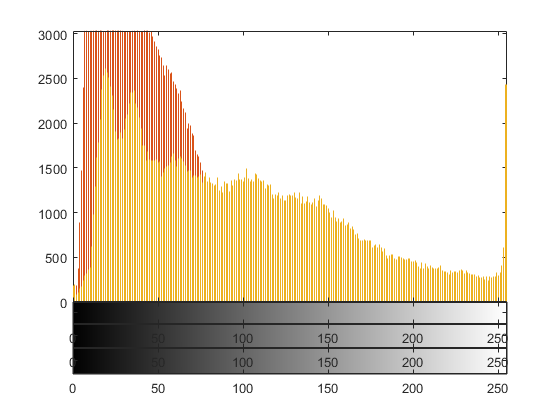

figure(12);
imhist(image1_gray);

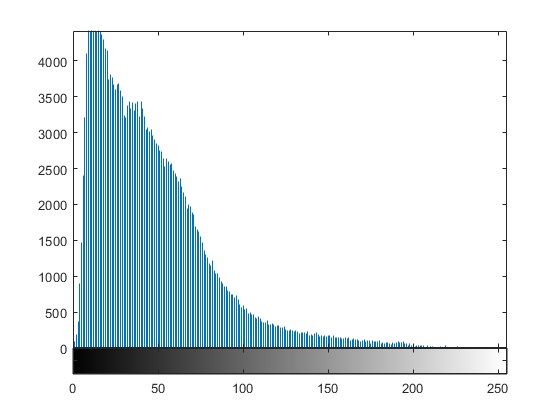

figure(17);
imhist(image2_gray);

Modyfikacja zdjęcia nastąpiła między innymi poprzez zwiększenie kontrastu i przyciemnienie, zwiększenie kontrastu powoduje usunięcie środkowego pasma odcieni szarości, nastomiast przyciemnienie usuwa pasmo bardzo jasnych odcieni szarośći, co widać na histogramach.

## 6.

Odległość między odpowiadającymi pikselami obrazu.

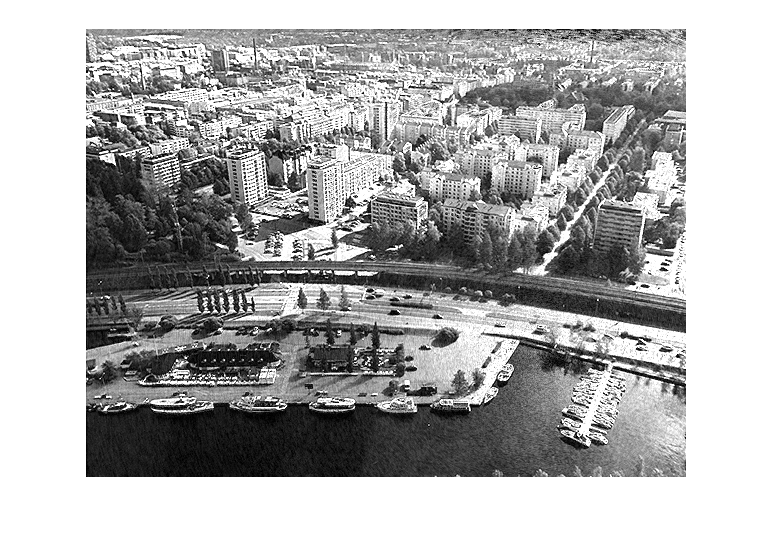

F = getEucDistanceImage(image1_gray, image2_gray);
F = F / 100;
figure(13);
imshow(F);

Przyglądając się obrazowi wygenerowanemu na podstawie odleg

Funkcja poniżej zwraca macierz odleglosci miedzy obrazami

function distanceImage = getEucDistanceImage(image1, image2)
    distanceImage = sqrt(sum((double(image1) - double(image2)).^2, 3));
end